# Working with the `cvpartition` function

Splitting the data set into a training/validation set and a test set is one of the first steps in the machine learning workflow. In this reading, you'll practice using the `cvpartition` function to obtain a test data set for both regression and classification applications and address potential issues that may arise with smaller data sets or class imbalance.

## Example Data Set

### Setting the Seed

Several of the functions you'll use will involve generating random numbers to select and partition data. To make the results reproducible, i.e., get the same random results each time you run this script, you can set the random number generator seed like this:

rng(11)

### Health Example

Generate a small dataset and use it to understand how the `cvpartition` function splits data for different use cases. The small data set is used to illustrate concepts harder to see with a larger data set.

Status = categorical([repmat("sick",6,1);repmat("healthy",6,1)]);
PatientID = (1:length(Status))';
Indicator = randi([40 150],size(Status));
healthData = table(PatientID,Indicator,Status)

## Using the table height for random splitting

Let's start by looking at a **regression problem**, where you want to **predict** the **indicator values** from the table `healthData`. The first step in solving this problem is randomly splitting the data into a training/validation set and a test set. To do that first split, you need to: 

- Use the `cvpartition` function with the height of the table for random splitting. This operation will create a cvpartition object.

- Apply the `training` and `test` functions to extract the indices to the training/validation and test samples.

- Create** two separate data sets** for training/validation and test with the indices from step 2.

An earlier reading demonstrated how to use the `cvpartition` function with the height of the data set as the first input and the "Holdout" option. The result of the `cvpartition` function will be a partition, containing *randomly* selected indices for the training and test data.

healthData_holdout = cvpartition(height(healthData),"Holdout",0.4)

To extract these indices, apply the training and test functions to `healthData_holdout`. The following lines of code go one step further and create separate tables for the training and test data sets.

trainingDataR = healthData(training(healthData_holdout),:)
testDataR = healthData(test(healthData_holdout),:)

Execute *this section* several times and observe how the data sets change, especially the test set. Now assume you are working on a classification problem and wish to predict the "Status" variable. Notice that with this small data set, it's possible to have the test set samples as either all "sick" or all "healthy." Using the syntax mentioned above is usually fine with a large amount of data, where misrepresenting data would not happen. 

## Using the response variable for a balanced class representation

Misrepresenting data becomes an issue with **smaller data sets** or with **imbalanced classes**. When all the test samples belong to one class, how would you assess a machine learning model on this test set? There would be no way to see how the model performs on the other class. 

   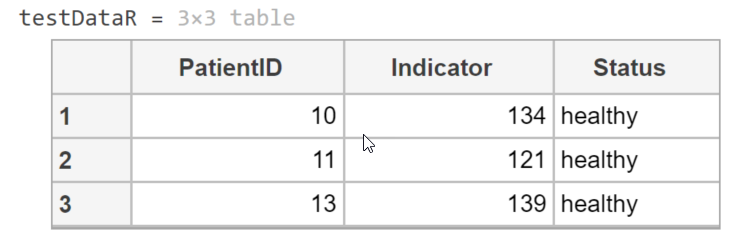

When splitting data into the training/validation set and the test set, the goal is to have all classes represented accurately in every data set. In this classification problem, the categorical table variable "Status" represents the two classes in the data, "healthy" and "sick." With this variable as the first input to the `cvpartition` function, the class information will be used to split the data. As a result, the training/validation set and the test set will have roughly the same class proportions as in the original data set. Apply the `training` and `test` function as before to create the training and test set variables.

healthData_holdout = cvpartition(healthData.Status,"Holdout",0.4)

trainingDataC = healthData(training(healthData_holdout),:)
testDataC = healthData(test(healthData_holdout),:)

Also re-run *this section* several times. Notice that, `cvpartition` ensures that samples from each class are included in the test set.

**Now it's your turn: **Change the data set, so that the classes have an imbalance, e.g. such as "healthy" appears three times, and "sick" nine times.

numberSick = 3;
Status = categorical([repmat("sick",numberSick,1);repmat("healthy",(12-numberSick),1)]);
PatientID = (1:length(Status))';
Indicator = randi([40 150],size(Status));
healthDataTask = table(PatientID,Indicator,Status)

Follow the steps explained above to split the data set in `healthDataTask` into training/validation set and test set:

- Use the `cvpartition` function to create a cvpartitioning object.

- Apply the `training` and `test` functions to extract the indices to the training/validation and test samples.

- Create** two separate data sets** for training/validation and test with the indices from step 2. Is your test set a good representation of the full data set? 

% put your code here